# 上机练习 3

本次练习包含了Canny边缘检测以及Hough变换的相关内容

## 模块 1: Canny 边缘检测 (85 points)

在本模块中，你需要建立一个Canny边缘检测器. Canny边缘检测的步骤可以分为:

- 图片平滑

- 计算梯度

- 非极大值抑制

- 双阈值

- 抓取边缘

**1.1 图片平滑 (10 points)**

我们首先了利用高斯滤波器来对图片进行平滑处理. 大小为$\left(2k+1\right)\times \left(2k+1\right)$的高斯滤波器可以由以下方程给出：


$$h_{i j}=\frac{1}{2 \pi \sigma^{2}} \exp \left(-\frac{(i-k)^{2}+(j-k)^{2}}{2 \sigma^{2}}\right), 0 \leq i, j<2 k+1$$


完成 `gaussian_kernel` 函数并运行以下代码.

% 定义一个 3x3 的高斯 kernel，并将其sigma值设为 1
kernel = gaussian_kernel(3, 1)

kernel =     0.0585    0.0965    0.0585
    0.0965    0.1592    0.0965
    0.0585    0.0965    0.0585


kernel_test = [[ 0.05854983, 0.09653235, 0.05854983],
     [ 0.09653235, 0.15915494, 0.09653235],
     [ 0.05854983, 0.09653235, 0.05854983]];

% 检测生成的高斯kernel是否正确
if sum(sum(kernel-kernel_test))>1e-4
    disp('代码有误！')
end

% 用不同的尺寸以及sigma值来进行测试
kernel_size = 5

kernel_size = 5

sigma = 1.4

sigma = 1.4000

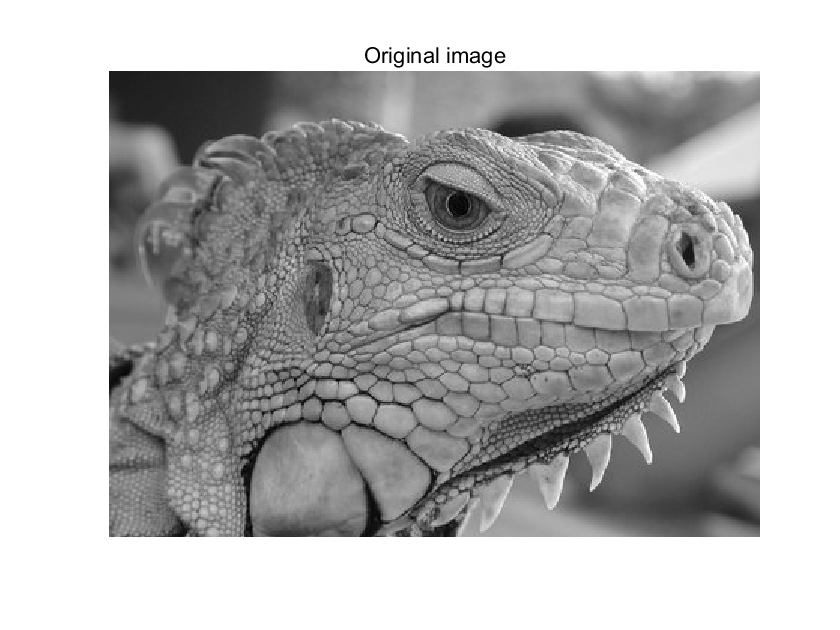


% 载入图片
img = imread('iguana.png');
img = double(rgb2gray(img))/255;

% 生成高斯kernel
kernel = gaussian_kernel(kernel_size, sigma);

% 利用kernel来对图片进行平滑
smoothed = conv2(img, kernel, 'same');

imshow(img,'InitialMagnification','fit');
title('Original image')

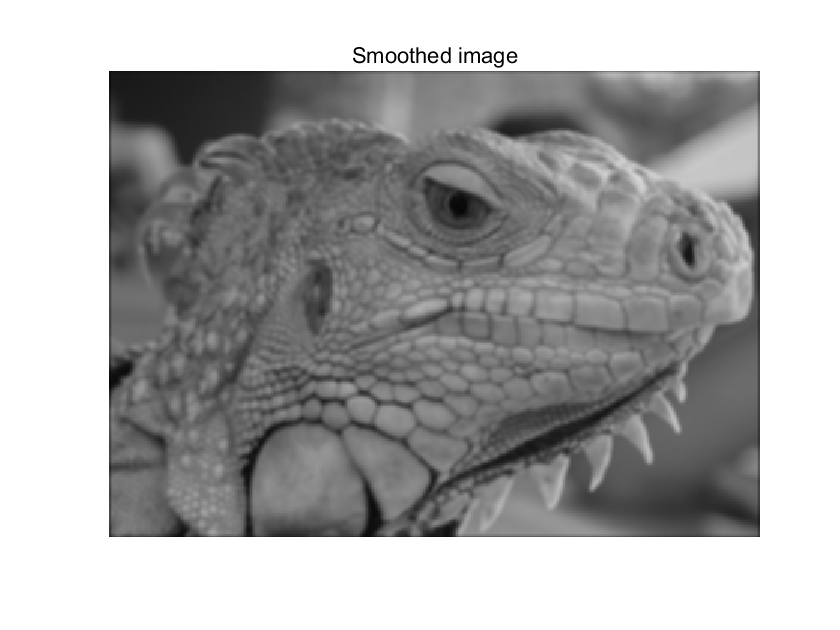


imshow(smoothed,'InitialMagnification','fit');
title('Smoothed image');

## 问题 (5 points)

改变 kernel_size 以及 sigma分别具有什么效果?

答：kernel_size（高斯核的大小）：

高斯核的大小决定了平滑操作的邻域范围。核越大，平滑效果越明显，因为更多的像素值被平均考虑在内。大的核会导致图像细节丢失更多，因为更多的像素被融合在一起。相反，小的核会保留更多的图像细节，因为平滑操作只涉及较少的像素。

sigma（高斯分布的标准差）：

标准差决定了高斯分布的宽度，即权重随距离增加而减小的速度。较大的 sigma 值意味着权重随距离增加而减小得更慢，因此较远的像素也会对中心像素的值产生较大影响。这会导致图像变得更加平滑，因为更多的像素（即使它们距离较远）也会对中心像素的值做出贡献。较小的 sigma 值会使权重随距离增加迅速减小，因此只有附近的像素对中心像素的值有显著影响，这会导致平滑效果较弱。

## 1.2 计算梯度 (15 points)

二维梯度函数$I:{R}^2\rightarrow{{R}}$可以定义成:


$$\nabla{I(x,y)}=\bigl[\frac{\partial{I}}{\partial{x}},\frac{\partial{I}}{\partial{y}}\bigr],$$


其中


$$\frac{\partial{I(x,y)}}{\partial{x}}=\lim_{\Delta{x}\to{0}}\frac{I(x+\Delta{x},y)-I(x,y)}{\Delta{x}} \\
\frac{\partial{I(x,y)}}{\partial{y}}=\lim_{\Delta{y}\to{0}}\frac{I(x,y+\Delta{y})-I(x,y)}{\Delta{y}}.$$


对于图像, 我们可以用差分代替微分:


$$\frac{\partial{I(x,y)}}{\partial{x}}\approx{\frac{I(x+1,y)-I(x-1,y)}{2}} \\
\frac{\partial{I(x,y)}}{\partial{y}}\approx{\frac{I(x,y+1)-I(x,y-1)}{2}}$$


注意：差分运算可以表示成图片$I$与恰当的卷积核$D_x$ 和 $D_y$的卷积运算:


$$\frac{\partial{I}}{\partial{x}}\approx{I*D_x}=G_x \\
\frac{\partial{I}}{\partial{y}}\approx{I*D_y}=G_y$$


## 完成梯度运算

找出求取图像差分所对应的卷积核$D_x$ 和 $D_y$，利用`conv2`函数完成 **`partial_x`** and **`partial_y`**.

*-注意: 卷积操作会将kernel给反转以下，不要弄反了哦.*

% 测试案例
I = [[0, 0, 0],
     [0, 1, 0],
     [0, 0, 0]];

% 希望的输出结果
I_x_test = [[ 0, 0, 0],
     [ 0.5, 0, -0.5],
     [ 0, 0, 0]];

I_y_test =[[ 0, 0.5, 0],
     [ 0, 0, 0],
     [ 0, -0.5, 0]];

% 计算梯度
I_x = partial_x(I)

I_x =          0         0         0
    0.5000         0   -0.5000
         0         0         0


I_y = partial_y(I)

I_y =          0    0.5000         0
         0         0         0
         0   -0.5000         0



% 确定partial_x and partial_y是否编写正确
disp('验证梯度计算是否正确：')

验证梯度计算是否正确：


disp(I_x == I_x_test);

   1   1   1
   1   1   1
   1   1   1



disp(I_y == I_y_test);

   1   1   1
   1   1   1
   1   1   1



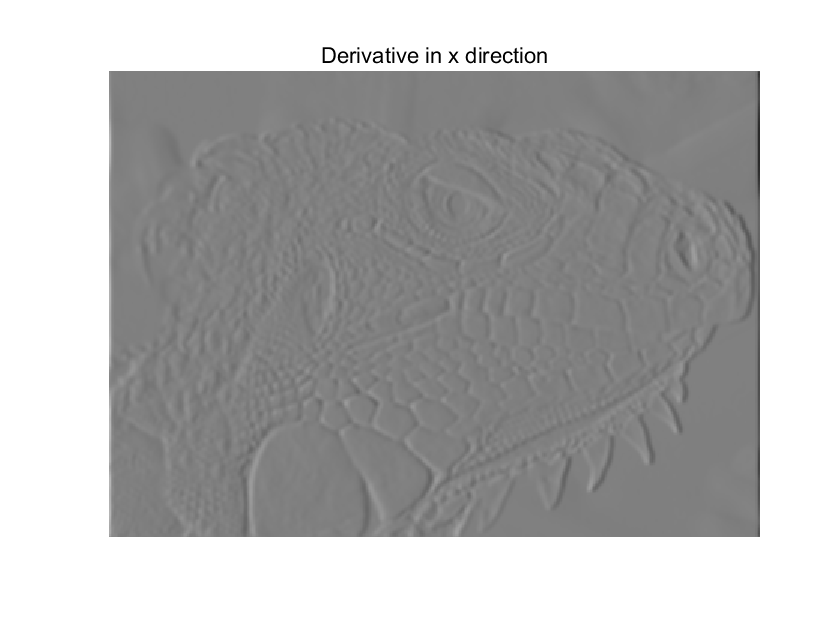


% 计算平滑后的图像的差分
Gx = partial_x(smoothed);
Gy = partial_y(smoothed);

imshow(Gx+0.5,'InitialMagnification','fit');%让背景为灰色
title('Derivative in x direction')

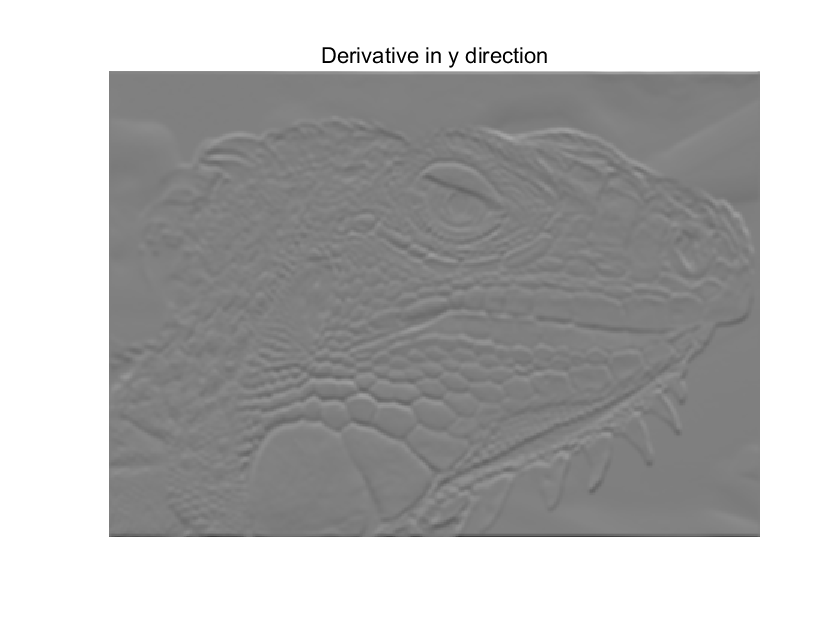


imshow(Gy+0.5,'InitialMagnification','fit');
title('Derivative in y direction')

## 问题 (5 points)

为什么在计算梯度之前要进行平滑处理?

答：在计算梯度之前进行平滑处理是为了减少图像中的噪声干扰，增强梯度计算的稳定性和准确性，同时保护图像的边缘特征，从而提高后续图像处理步骤的效果，尽管这可能会带来一定程度的图像模糊。

现在，让我们用两个方向的差分来计算图片的梯度大小以及方向:


$$G = \sqrt{G_{x}^{2}+G_{y}^{2}} \\
\Theta = arctan\bigl(\frac{G_{y}}{G_{x}}\bigr)$$


完成**`gradient`**函数，计算梯度$G$和梯度方向$\textrm{Theta}$.

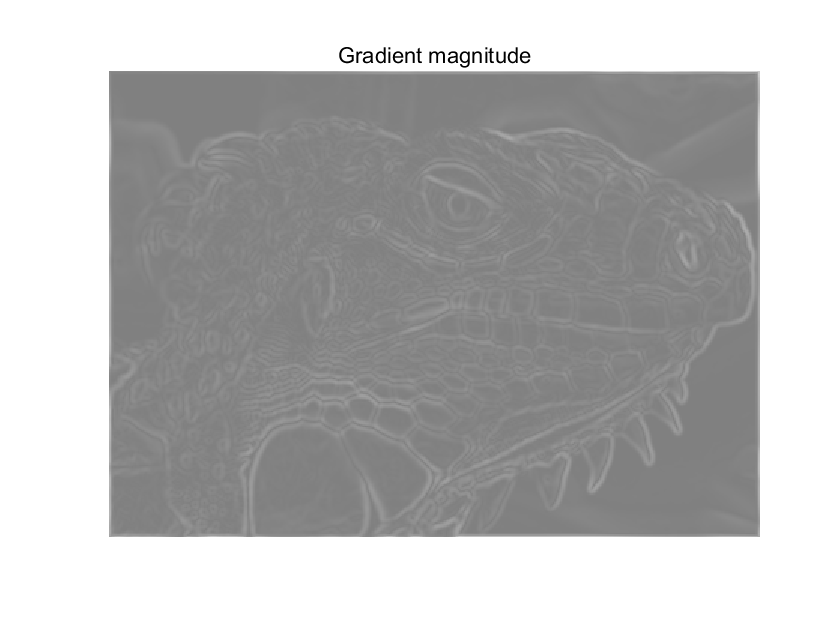

[G, theta] = gradient(smoothed);

if min(G(:) < 0)
    disp('梯度幅值肯定大于0.');
end
    
if min(theta(:))<0 || max(theta(:))>360
    print('梯度角度需要在0到360°之间')
end

imshow(G+0.5,'InitialMagnification','fit');%+0.5让背景为灰色
title('Gradient magnitude');

## 1.3 非极大值抑制 (15 points)

可以发现，找出来的梯度图像比较粗大并且模糊，并不适合直接用来表示的边缘。 此时我们可以利用非极大值抑制的方法来找出“尖锐”的边缘。简单来说，这可以通过保留（梯度）图像中的局部极大值点并且抛弃其他点来进行。具体的算法如下:

1. 将梯度方向 Theta 取整到最接近它的45°方向上。

2. 沿着梯度方向（和反方向），比较当前像素点与其邻域的像素点的梯度值大小。 例如，如果梯度方向是正南方 (theta=90°), 比较该像素点南边（也就是该像素点下方的像素点）以及该像素点北边（也就是该像素点上方的像素点）的梯度值大小.

3. 若该点是局部极大值（包括相等），则保留. 否则，移除该点.

完成 **`non_maximum_suppression`** 函数 .

这里提供了正确的结果作为参照，如果发现在差异图上存在两点，那最好重新检查下算法是否正确。

% 测试例
g = [[0.4, 0.5, 0.6],
     [0.3, 0.5, 0.7],
     [0.4, 0.5, 0.6]];

% 输出非极大值抑制的结果
% 改变梯度方向：通过四个方向来测试，即0,45,90,135。你可以将输出结果与自己笔算的结果做对比。
for angle =[0,45,90,135]
    disp('Thetas:');disp(angle);
    t = ones(3, 3) * angle % 初始化 theta
    disp(non_maximum_suppression(g, t));
end

Thetas:
     0



t =      0     0     0
     0     0     0
     0     0     0


错误使用 alpha
输出参数太多。

出错 non_maximum_suppression (line 12)
        dirc = alpha(i, j);         % 四个基本方向判断并进行非最大抑制，比如矩阵是


%对图像进行操作
subplot(1, 3, 1);
nms = non_maximum_suppression(G, theta);
imshow(nms+0.5);
title('Non-maximum suppressed');

load('mat_name.mat'); %载入参考值
subplot(1, 3, 2);
imshow(data+0.5);
title('Reference');

img_difference = nms-data;
subplot(1, 3, 3);
imshow(img_difference+0.5);
title('Difference');
if(max(max(img_difference)) > 0.01)
    disp('请检查你的代码');
end

## 1.4 双阈值 

在经过非极大值抑制后，仍然存在许多像素点。这些像素点有些是边缘，但有些是由噪声或者颜色变化（例如粗糙的表面）所导致的。要消除这部分影响，最简单的方式是增加一个阈值判定，只允许相应强度大于阈值的点被标记成边缘。Canny边缘检测算法采用了双阈值算法。大于高阈值的像素点被标记为强边缘，小于低阈值的像素点可以认为是非边缘并且被移除，而在高低阈值之间的点被标记为弱边缘。

完成函数 **`double_thresholding`** 

low_threshold = 0.02;
high_threshold = 0.03;

[strong_edges, weak_edges] = double_thresholding(nms, high_threshold, low_threshold);
if sum(all(strong_edges & weak_edges)) > 0
    disp('计算错误');
end

edges=strong_edges * 1.0 + weak_edges * 0.5;

figure;
subplot(1,2,1)
imshow(strong_edges)
title('Strong Edges')

subplot(1,2,2)
imshow(edges)
title('Strong+Weak Edges')

## 1.5 找出边缘 (15 points)

通常而言，强边缘被认为是“肯定的边缘”, 因此可以直接认为该像素点就是边缘. 而弱边缘则需要进一步判断。如果弱边缘点与边缘相连接，则认为该像素点是边缘。这背后的逻辑是这样的：噪声或者颜色变化点不太可能产生强边缘（如果设定好恰当对的阈值范围），因此强边缘只能由源图像中的边缘产生。而弱边缘可由边缘产生，也可以由噪声和颜色变化产生。而由噪声和颜色变化产生的弱边缘点，一般来说都均有分布在整幅图片上，只有一小部分是与强边缘相连接的，大部分与强边缘相连接的点都是真实的边缘像素点。

完成**`link_edges`** 函数.

运行一下代码并观察difference 图像是否有明显的白点, 如果存在（除了边缘外）,可能你的函数存在问题.  

提示：测试例中像素点[2,0]属于弱边缘，但它也和边缘相连，因此也被认为是边缘像素点。

test_strong = [[1, 0, 0, 0],
     [0, 0, 0, 0],
     [0, 0, 0, 0],
     [0, 0, 0, 1]];

test_weak = [[0, 0, 0, 1],
     [0, 1, 0, 0],
     [1, 0, 0, 0],
     [0, 0, 1, 0]];

test_linked = link_edges(test_strong, test_weak);

figure;
subplot(1, 3, 1)
imshow(test_strong)
title('Strong edges')

subplot(1, 3, 2)
imshow(test_weak)
title('Weak edges')

subplot(1, 3, 3)
imshow(test_linked)
title('Linked edges')

%对图片进行处理
edges = link_edges(strong_edges, weak_edges);

figure;
imshow(edges,'InitialMagnification','fit');

figure;
subplot(1, 3, 1);
imshow(edges);
title('Your result');

subplot(1, 3, 2);
load ref.mat
imshow(ref);
title('Reference');

subplot(1, 3, 3);
imshow(edges - ref);
title('Difference');

## 1.6 Canny 边缘检测

利用前面你所完成的函数补全**`canny`** 函数,用不同的参数来测试canny函数。

这是一个输出结果:

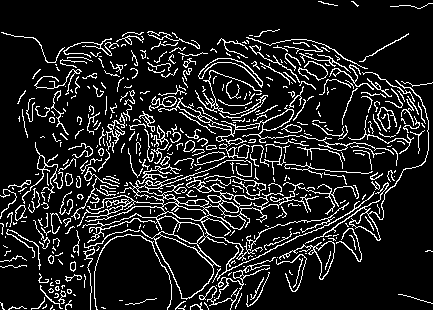

这里我们提供正确的输出结果以及它与你输出结果之间的差异图像，以方便你来测试。如果你看到差异图像存在白点，那么可能你的实现存在一些问题.


% 载入图像
img = imread('iguana.png');
img = double(rgb2gray(img))/255;

% 运行canny边缘检测器
edges = canny(img, 5, 1.4, 0.03, 0.02);
disp('The size of the image is :')
disp (size(edges));

figure;
subplot(1, 3, 1);
imshow(edges);
title('Your result');

subplot(1, 3, 2);
load edges.mat
imshow(ref);
title('Reference');

subplot(1, 3, 3);
imshow(edges - ref);
title('Difference');

# 模块2: 道路检测

在本模块，我们将利用Canny边缘检测器以及Hough变换实现简单的道路检测。.

这是两张通过道路检测算法检测出来的结果：

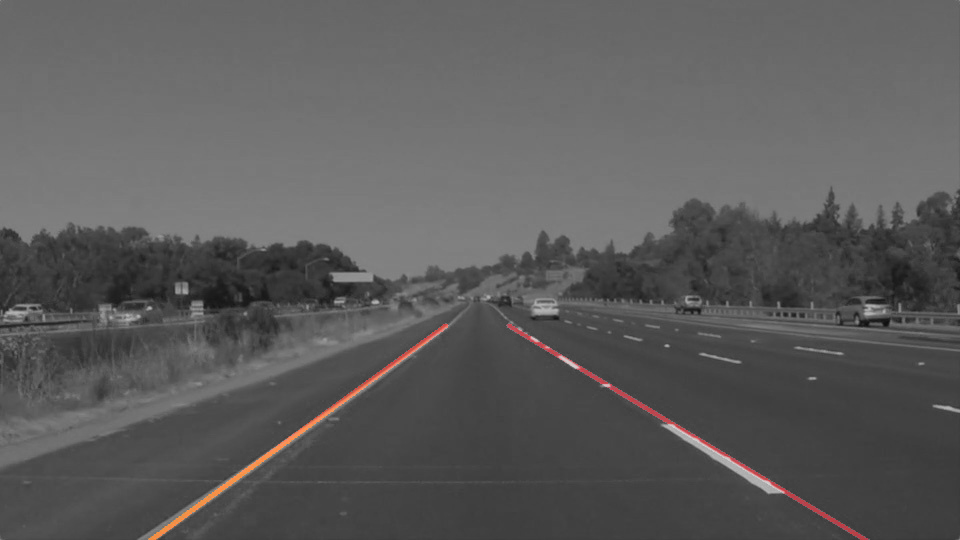

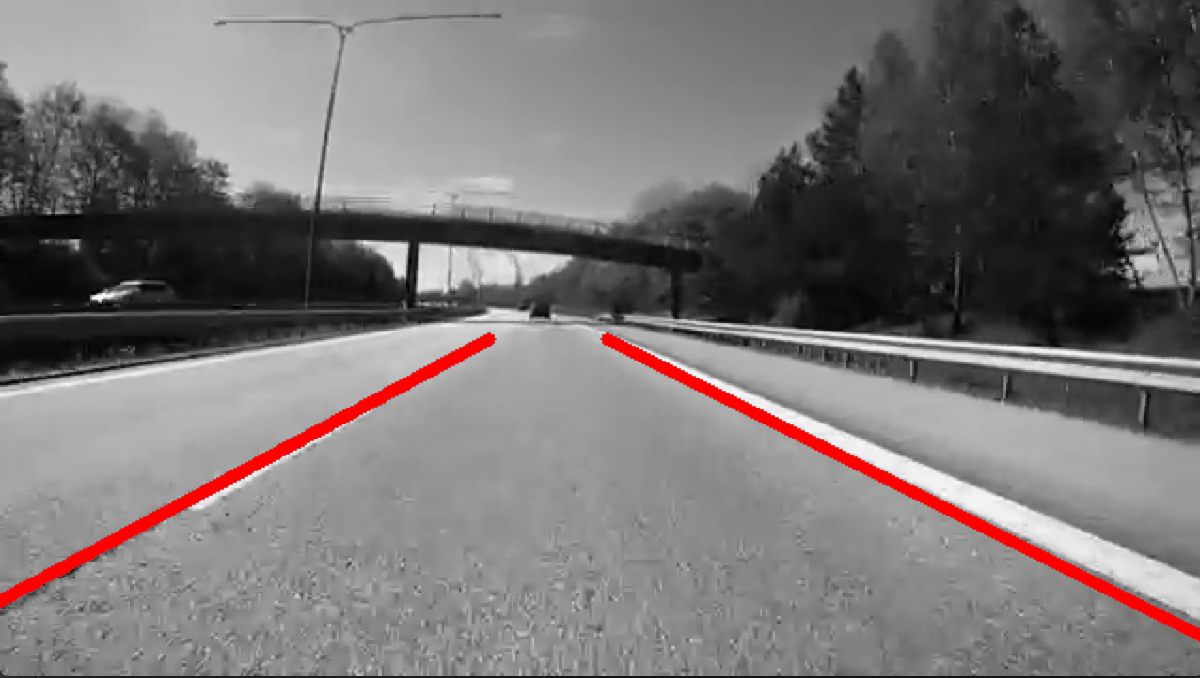

这个算法的步骤如下:

1. 利用Canny检测边缘.

2. 抓取出感兴趣区域（region of interest, ROI）的边缘 (一个三角形所定义的区域，包含了底部以及画面中心).

3. 利用Hough变换来检测道路.

## 2.1 边缘检测

通常而言，车道都是细长的直线，并且具有较高的亮度。这种条件保证了它能被我们的算法较好地检测出来。运行下面代码，载入图片并检测图片中的边缘。


% 载入图片
img = imread('road.jpg');
img = double(rgb2gray(img))/255;

% 利用canny算子进行边缘检测
edges = canny(img, 5, 1.4, 0.03, 0.02);

figure;
imshow(img);
title('Input Image');

imshow(edges);
title('Edges');

## 2.2 抓取感兴趣区域 (ROI)

可以发现，Canny算法能够找出图片中的道路. 但是，我们也可以看到这里面出现了很多我们不需要的物体的边缘。考虑到所抓取的图片的空间位置，我们清楚道路总是在图片的下半部分，因此可以利用这一点消除一部分不希望得到的边缘。下面的代码定义了一个二值化的模板（mask），用来抓取我们感兴趣的区域的边缘。

[H, W] = size(img);

% 生成ROI区域
mask = zeros(H, W);
for i=1:H
    for j=1:W
        if i > (H / W) * j && i > -(H / W) * j + H %定义我们所感兴趣部分在途中的中间偏下位置，具体可以查看mask的图形。
            mask(i,j) = 1;
        end
    end
end

for i=1:H
    for j=1:W
        if i > (H / W) * j && i > -(H / W) * j + H %定义我们所感兴趣部分在途中的中间偏下位置，具体可以查看mask的图形。
            mask(i,j) = 1;
        end
    end
end
% 提出ROI区域的边缘
roi = edges .* mask;
roi(end,:) = 0;
roi(:,[1,end]) = 0;

figure;
subplot(1,2,1);
imshow(mask);
title('Mask');

subplot(1,2,2);
imshow(roi);
title('Edges in ROI');

## 2.3 利用Hough变换找出直线

尽管我们利用了mask把边缘限制在了ROI区域，但是所找出的边缘仍旧是一团像素点，而不是连在一起的直线。一般的，我们习惯于用参数方程 $y=a\;x+b$来表示直线。它的斜率是 $a$ 而截距是 $b$。在这里，我们利用Hough变换来寻找这条直线。

通常，直线 $y=a\;x+b$ 可以表示成参数空间 $\left(a,b\right)$的一个点。但它不能表示竖直方向的直线，所以我们采用了极坐标形式的参数$\theta\in{[-\pi, \pi]}$ 和 $\rho\in{{R}}$ 来表示直线:


$$\rho = x\cdot{cos\theta} + y\cdot{sin\theta}$$


利用极坐标的表示方法，我们就将 $x-y$空间转到了$\rho -\;\theta$空间 (或者说Hough空间)。带入不同边缘像素点的坐标[x,y]，我们就可以得到$\rho -\;\theta$空间的一系列曲线，曲线的交点就是我们所求的参数$\rho -\;\theta$。这样，我们就求得了极坐标下直线的方程，也可以进一步地将其转成 $x-y$空间的直线方程。

在求取曲线的交点的过程中，我们可以避免直接对交点进行求取，而是某个点被多少条曲线经过。例如，曲线1经过了点p1,p2,p3,曲线2经过了点p3,p4,p5,那么点p3的计数值就是2，而点p1,p2,p4,p5的计数值就是1，这样通过比较计数值，我们可以确定点p3就是曲线的交点。

*参考http://web.ipac.caltech.edu/staff/fmasci/home/astro_refs/HoughTrans_lines_09.pdf).*

完成 **`hough_transform`** 函数.

% 对ROI区域的边缘像素点作Hough变换
[acc, rhos, thetas] = hough_transform(roi);

[~,idx] = sort(acc(:),'descend');  %按找出来的交点个数进行排序
[r_idx, t_idx]=ind2sub(size(acc), idx);  %计算坐标，以及对应的rho和theta
rho = rhos(r_idx);                
theta = thetas(t_idx);

% 将Hough空间（ρ-θ空间）变换到x-y空间.
a = - (cosd(theta)./sind(theta)); % 斜率
b = (rho./sind(theta)); % 截距

%根据a判断是左边的道路还是右边的道路
%左边的道路是向左下方的，所以a<0
%右边的是向右下方的，所以a>0
%左右两边的a值符号是相反的
flag = 0;%用来确定找出几条直线
figure;
imshow(img);
hold on;
for i=1:length(a)
    if flag == 0
        a1 = a(1);
    elseif flag==2
        break;
    elseif a(i) * a1 > 0 %找出来的两条直线的a值应该不同符号
           continue;
    end
    flag = flag+1 ;
    as=a(i);%画出道路
    bs=b(i);
    xs=1:size(img,2);%我们只考虑ROI区域里面的点
    ys= as * xs + bs;
    idx = ys >0  & ys < size(img,1) * 0.4;
    %注意，当imshow之后，plot的原点从左下角变成了左上角，
    %并且水平方向为x轴竖直方向为y轴，因此需要进行坐标转换
    plot(xs(idx), round(540-ys(idx)),'LineWidth',5);
end

